Step 1: Load the data and preprocess it.

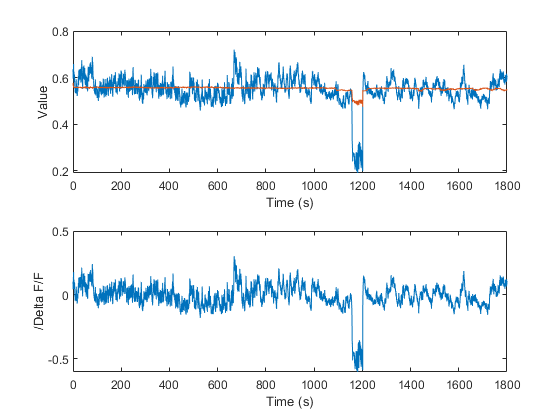

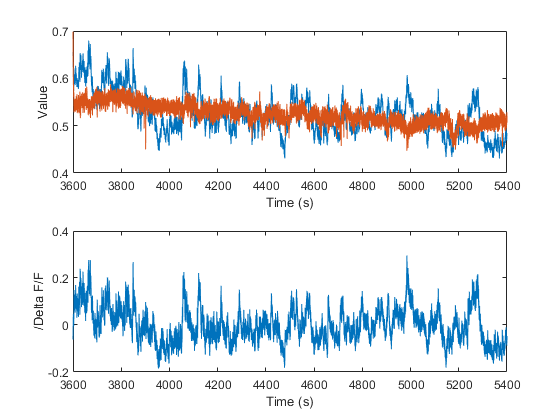

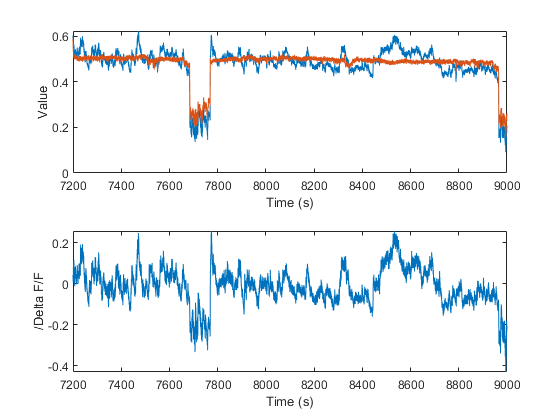

clear; close all; clc
filename = 'SA57_NAc_011923_0001'; 

% Data_Acquired = ExtractDataAcquisition([filename, '.doric');
% ProcessedData_filename = {[filename, '_DFF001'], [filename, '_DFF002'], [filename, '_DFF003']};
rawdata_tree = '/DataAcquisition/FPConsole/Signals/';
setting_tree = '/Configurations/FPConsole/AIN02/Settings/';
% processed_data_tree = '/DataProcessed/FPConsole/DFFSignals/';
Seriers = {'Series0001', 'Series0002', 'Series0003'};
EventVariables = {'DataAcquisition_FPConsole_Signals_Series0001_DigitalIO', ...
    'DataAcquisition_FPConsole_Signals_Series0002_DigitalIO', ...
    'DataAcquisition_FPConsole_Signals_Series0002_DigitalIO'};

for i = 1:length(Seriers)
    ProcessedData(i).Seriers = Seriers{i};
    ProcessedData(i).settings.Sig405_output  = h5readatt([filename, '.doric'], [setting_tree, 'LockInAOUT1'], 'OtputLevel');
    ProcessedData(i).settings.Sig470_output  = h5readatt([filename, '.doric'], [setting_tree, 'LockInAOUT2'], 'OtputLevel');    
    ProcessedData(i).rawData.Sig405   = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/AIN02xAOUT01-LockIn/Values']);
    ProcessedData(i).rawData.Sig470   = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/AIN02xAOUT02-LockIn/Values']);
    ProcessedData(i).rawData.time     = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/AIN02xAOUT02-LockIn/Time']);
%     ProcessedData(i).processed.signal = h5read([ProcessedData_filename{i}, '.doric'], [processed_data_tree, Seriers{i}, '/AIN02xAOUT02-LockIn/Values']);
%     ProcessedData(i).processed.time = h5read([ProcessedData_filename{i}, '.doric'], [processed_data_tree, Seriers{i}, '/AIN02xAOUT02-LockIn/Time']);
    ProcessedData(i).rawDIO.lever     = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/DigitalIO/DIO01']);
    ProcessedData(i).rawDIO.infusion  = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/DigitalIO/DIO02']);
    ProcessedData(i).rawDIO.front     = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/DigitalIO/DIO03']);
    ProcessedData(i).rawDIO.back      = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/DigitalIO/DIO04']);
    ProcessedData(i).rawDIO.time      = h5read([filename, '.doric'], [rawdata_tree, Seriers{i}, '/DigitalIO/Time']);
    
    % fit 405 to 470 signals to calculate delta F/F
    Sig405 = ProcessedData(i).rawData.Sig405;
    Sig470 = ProcessedData(i).rawData.Sig470;
    [cleanedData,outlierIndices] = rmoutliers(Sig470,"quartiles","ThresholdFactor",3); % remove artifact from fitting. 
    % smooth 0.5 s;
    sample_rate = 1/mean(diff(ProcessedData(1).rawData.time));
    n = 0.5 * sample_rate;
    if mod(floor(n),2)
        scale = floor(n) + 1;
    else
        scale = floor(n);
    end
    F470=smooth(cleanedData,scale,'lowess');
    F405=smooth(Sig405(~outlierIndices),scale,'lowess');
    bls=polyfit(F405(1:end),F470(1:end),1);
    Y_Fit=bls(1).*Sig405+bls(2);
    Delta470=(Sig470(:)-Y_Fit(:))./Y_Fit(:);
    ProcessedData(i).processed.signal = Delta470;
    ProcessedData(i).processed.time = ProcessedData(i).rawData.time;
    ProcessedData(i).processed.Fit405 = Y_Fit;
    figure;
    subplot(2,1,1)
    plot(ProcessedData(i).processed.time, Sig470)
    hold on
    plot(ProcessedData(i).processed.time, Y_Fit)
    xlabel('Time (s)')
    ylabel('Value')
    subplot(2,1,2)
    plot(ProcessedData(i).processed.time, Delta470)
    xlabel('Time (s)')
    ylabel('\Delta F/F')
end

save([filename, '_processed.mat'], 'ProcessedData')


DO NOT RUN THIS!!!!! IT IS FOR TESTING.

% remove the artifacts
Sig405 = ProcessedData(3).rawData.Sig405;
Sig470 = ProcessedData(3).rawData.Sig470;

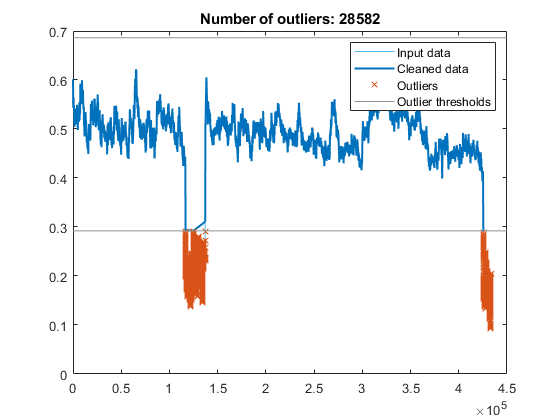

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(Sig470,"quartiles",...
    "ThresholdFactor",3);

% Display results
clf
plot(Sig470,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),Sig470(outlierIndices),"x","Color",[217 83 25]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(Sig470,"quartiles",...
    "ThresholdFactor",3);

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend

clear thresholdLow thresholdHigh

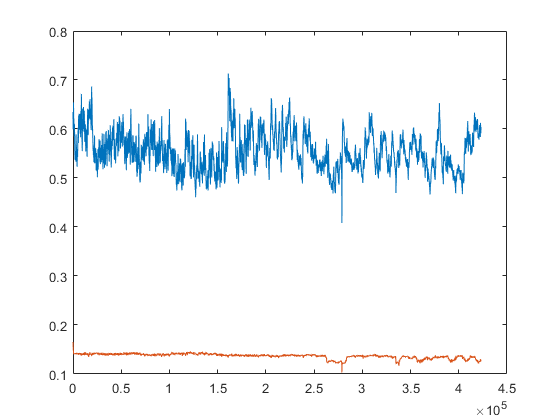

% smooth 0.5 s;
sample_rate = 1/mean(diff(ProcessedData(1).rawData.time));
n = 0.5 * sample_rate;
if mod(floor(n),2)
    scale = floor(n) + 1;
else
    scale = floor(n);
end
F470=smooth(cleanedData,scale,'lowess');
F405=smooth(Sig405(~outlierIndices),scale,'lowess');
figure;
plot(F470)
hold on
plot(F405)

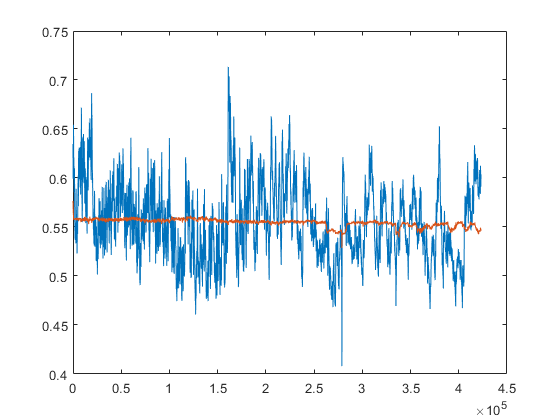

bls=polyfit(F405(1:end),F470(1:end),1);
Y_Fit=bls(1).*F405+bls(2);
figure;
plot(F470)
hold on
plot(Y_Fit)

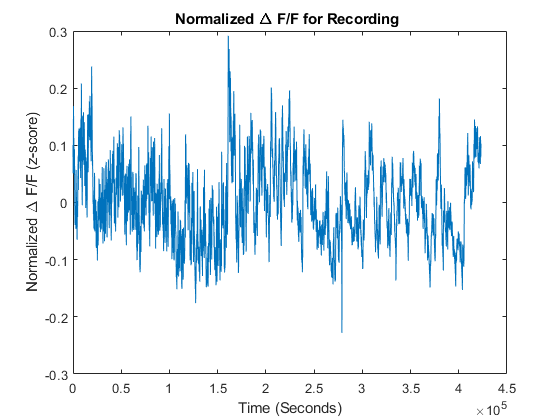

% save([filename, '_processed.mat'], 'ProcessedData')
Y_Fit=bls(1).*Sig405+bls(2);
figure;
Delta470=(Sig470(:)-Y_Fit(:))./Y_Fit(:);
plot(Delta470)
% % Delta F/F
hold on
plot(ProcessedData(1).processed.signal /10)


Step2: Visulize the data and convert the event to timestamps

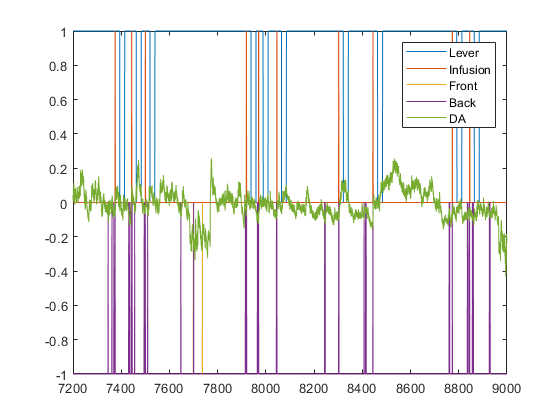

%% do some visualization
clearvars -except ProcessedData filename
i = 3;
figure
h1 = plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.lever* -1 + 1);
hold on;
h2 = plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.infusion* -1 + 1);
h3 = plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.front*-1);
h4 = plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.back*-1);
h5 = plot(ProcessedData(i).processed.time, ProcessedData(i).processed.signal);
legend({'Lever', 'Infusion', 'Front', 'Back', 'DA'})

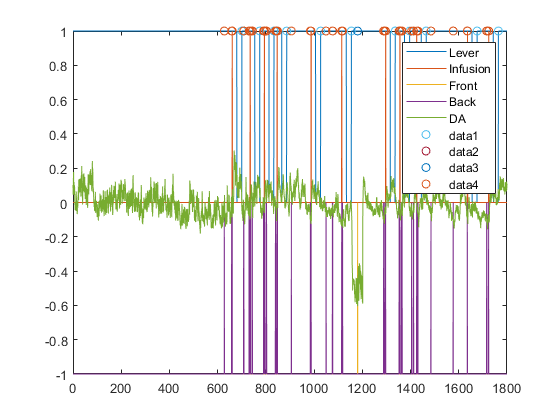

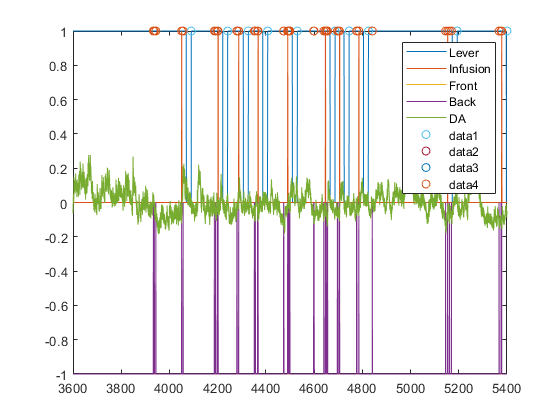

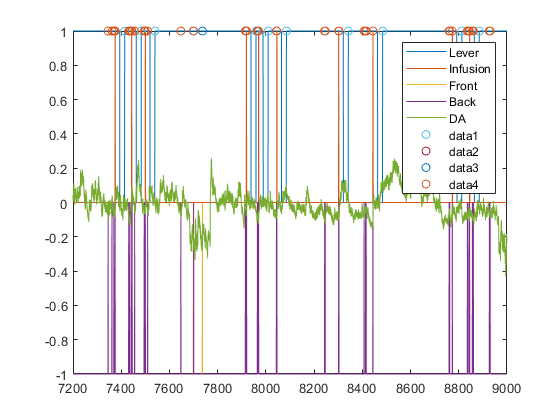


%% get the timestamps of each event.
for i = 1:length(ProcessedData)
    rawDIO = ProcessedData(i).rawDIO;
    [ProcessedData(i).DIO.lever_in, ProcessedData(i).DIO.lever_out]=Timing_onset_offset(rawDIO.lever, rawDIO.time, 0.5,1,0);
    ProcessedData(i).DIO.infusion = med_find_event(rawDIO.infusion, rawDIO.time);
    ProcessedData(i).DIO.front = med_find_event(rawDIO.front, rawDIO.time);
    ProcessedData(i).DIO.back = med_find_event(rawDIO.back, rawDIO.time);  
    figure
    plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.lever* -1 + 1)
    hold on
    plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.infusion* -1 + 1)
    plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.front*-1)
    plot(ProcessedData(i).rawDIO.time, ProcessedData(i).rawDIO.back*-1)
    plot(ProcessedData(i).processed.time, ProcessedData(i).processed.signal)
    legend({'Lever', 'Infusion', 'Front', 'Back', 'DA'})
    scatter(ProcessedData(i).DIO.lever_out, ones(size(ProcessedData(i).DIO.lever_out)))
    scatter(ProcessedData(i).DIO.infusion, ones(size(ProcessedData(i).DIO.infusion)))
    scatter(ProcessedData(i).DIO.front, ones(size(ProcessedData(i).DIO.front)))
    scatter(ProcessedData(i).DIO.back , ones(size(ProcessedData(i).DIO.back)))
end

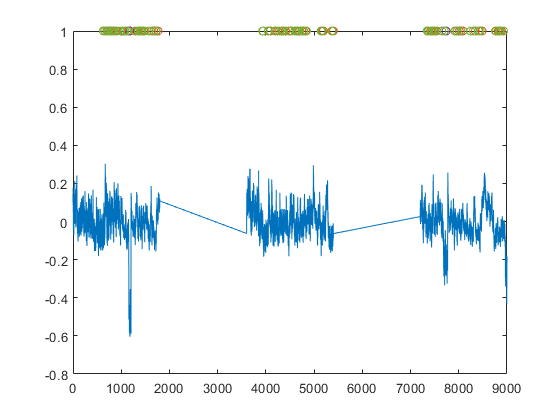

%% plot the psth for fb
% concatenate the data
Signal_concat = [ProcessedData(1).processed.signal; ProcessedData(2).processed.signal; ProcessedData(3).processed.signal];
Time_concat   = [ProcessedData(1).processed.time; ProcessedData(2).processed.time; ProcessedData(3).processed.time];
for i = 1:length(ProcessedData)
    if i ==1 
        DIO = ProcessedData(1).DIO;
    else
        fields = fieldnames(DIO);
        for k = 1:length(fields)
            DIO.(fields{k}) = [DIO.(fields{k}); ProcessedData(i).DIO.(fields{k})];
        end
    end
end
figure; plot(Time_concat, Signal_concat)
hold on
scatter(DIO.lever_out, ones(size(DIO.lever_out)))
scatter(DIO.infusion, ones(size(DIO.infusion)))
scatter(DIO.front, ones(size(DIO.front)))
scatter(DIO.back , ones(size(DIO.back)))

Plot the psth of the response

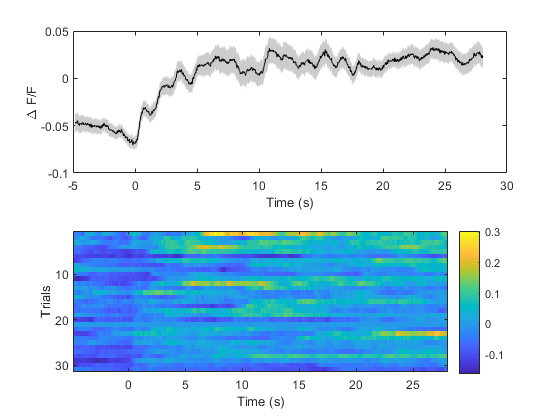

signal = Signal_concat;
time = Time_concat;
event = DIO.infusion;
pre = -5; % in secs
post= 29; % in secs
[psth_time,psth_signal] = psth_fb(signal,time, event, pre, post);

% save the data
data_table = table(signal, time);
save([filename, '_summary.mat'], 'data_table', 'DIO')